clear
%Creating leadlag controller 
f1 = 10; %[Hz] zero
f2 = 100; %[Hz] pole
leadlag = tf([1/(2*pi*f1) 1],[1/(2*pi*f2) 1])

leadlag =
 
  0.01592 s + 1
  --------------
  0.001592 s + 1
 
Continuous-time transfer function.
Model Properties



%Discretizing controller in various ways
Fs = 500;   %[Hz] sampling frequency
Ts = 1/Fs;  %[s] sampling time
C1 = leadlag;

C1 =
 
  0.01592 s + 1
  --------------
  0.001592 s + 1
 
Continuous-time transfer function.
Model Properties


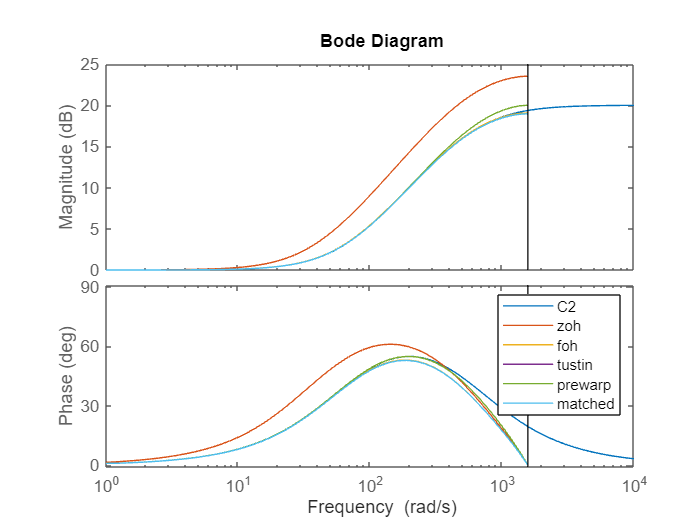

zoh = c2d(C1,Ts,'zoh');
foh = c2d(C1,Ts,'foh');
tustin = c2d(C1,Ts,'tustin');
opts = c2dOptions('Method','tustin','Prewarpfrequency',sqrt(f1*f2));
prewarp = c2d(C1,Ts,'tustin'); %tusting with specified prewarp
matched = c2d(C1,Ts,'matched');

%plotting the different controllers 
bode(C1)
hold on
bode(zoh); bode(foh); bode(tustin); bode(prewarp); bode(matched)
legend('C2','zoh','foh','tustin','prewarp','matched')
hold off

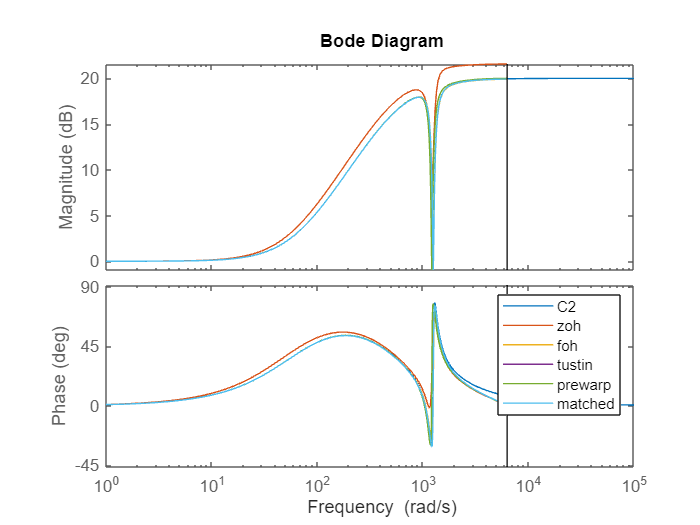

%creating notch filter
f1 = 200;   %[Hz]
f2 = f1;    %[Hz]
B1 = 0.01;  %damping factor zeros
depth = 20; %[dB]
B2 = B1 * 10^(depth/20); %damping factor poles
notch = tf([1/(2*pi*f1)^2 B1/(pi*f1) 1],[1/(2*pi*f2)^2 B2/(pi*f2) 1]); %notch fiter

%Discretizing controller in various ways
Fs = 2000;   %[Hz] sampling frequency
Ts = 1/Fs;  %[s] sampling time
C2 = leadlag*notch; %selected controller
zoh = c2d(C2,Ts,'zoh');
foh = c2d(C2,Ts,'foh');
tustin = c2d(C2,Ts,'tustin');
opts = c2dOptions('Method','tustin','Prewarpfrequency',sqrt(f1*f2));
prewarp = c2d(C2,Ts,'tustin'); %tusting with specified prewarp
matched = c2d(C2,Ts,'matched');

%plotting the different controllers 
bode(C2)
hold on
bode(zoh); bode(foh); bode(tustin); bode(prewarp); bode(matched)
legend('C2','zoh','foh','tustin','prewarp','matched')
hold off